# Assignment 3: ECSE 343: Numerical Methods in Engineering

Due Date: **18th March 2025**

Student Name: Deniz Karakus

Student ID: 261114510

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: You can write the functions in the appendix section .

## Question 1:  **(8 marks)**

You are given an orthonormal basis $\bf{Q} \in \mathbb{R}^{n\times q}$ which defines a subspace $\mathcal P$. You are also given a vector $\bf{b} \in \mathbb{R}^{n}$  which is not in that subspace   (i.e. $\bf{b} \notin \mathcal P$). 

a. Is it possible to express $\textbf{b}$ as  $\textbf{b} = \alpha_1  \textbf{ q}_1 + \alpha_2  \textbf{ q}_2+ \dots + \alpha_q   \textbf{ q}_q$ where$\textbf{ q}_1, \textbf{ q}_2, \dots, \textbf{q}_q$ are the columns of  $\textbf{Q}$ and $\( \alpha_1, \alpha_2, \dots  \alpha_q\)$ are the scalars? Justify your answer.

**No! By the definition of a subspace, if b is not in the same subspace **$\mathcal P$** as Q, we can't write b as a linear combination of the columns of the vector Q. Therefore, it is not possible to express b as a1q1+a2q2+...**

 b. Write the most efficient algorithm (a pseudocode) that you can develop for computing the vector $\bf{p} \in \mathbb{R}^{n}$, $\bf{p} \in \mathcal P$ which is the orthogonal projection of $\textbf{b}$ onto the subspace $\mathcal P$.

** function orthogonal_projection(Q, b):**

**    #could implement this using a loop, but direct matrix operations should be the most efficient **

**    #calculate Q^T* b**

**   temp = transpose(Q) * b**

**    #now calculate p = QQ^Tb**

**    return Q * temp **

## Question 2: **(10 marks)**

 You are given a vector $\mathbf{v}$ $\in \mathbb{R}^n$. Your task is to develop and implement an algorithm that computes an orthonormal matrix $\mathbf{Q} \in \mathbb{R}^{n \times n}$ such that $\mathbf{Q} \mathbf{v} = \mathbf{e}_1$, where $\mathbf{e}_1$ is the first column of the identity matrix. Write a MATLAB program that implements this algorithm. Explain why this algorithm works. How does it relate to the Householder QR algorithm?

function Q = computeOrthonormalMatrix(v)
    %get the unit vector v
    unit_v = v/norm(v);

    e1 = zeros(size(v));
    e1(1) = 1;

    %if unit vector is already in line with e1, just return identity matrix
    if norm(unit_v - e1) < 1e-15
        Q = eye(length(v));
        return;
    end

    %now use our equation that we've seen in class with the Householder 
    %householder vector
    u = e1 - unit_v;
    %householder transformation using the equation from the slides 
    Q = eye(length(v)) - 2 * (u*u')/(u'*u);

end

** Basically, we want a single householder reflection Q that sends the standard basis vector e1 to the normalized vector v/||v||. A Householder reflection flips vectors across the hyperplane that's orthogonal to u. By choosing u = e1 - unit_v, we force Qe1 to land exactly on the unit vector of v. In other words, we're "sending" e1 to v/||v|| using Q. This algorithm relates to the Householder QR algorithm because instead of applying a sequence of reflections to zero out below-diagonal entries of a matrix A, here we're only using one Householder reflection that sends e1 to v/||v||. We use the same equation as in the Householder method, but just once.  **

## Question 3:  QR Decomposition **(12 marks)**

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A);
   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') ;

**When I run the cell above, I get a norm of order 1e-16 which is effectively at machine precision. Or in other words, a very small norm, which means that the classical Gram-Schmidt based QR decompositon produced a very accurate factorization for this matrix. **

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

**For the cell below, we get a norm also of order 1e-16. Again, This small norm means the modified Gram-Schmidt approach produces a very accurate QR decomposition for this matrix. **

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A);
   
   normMGS = norm(A-Qmgs*Rmgs,'fro');  


c) We know that $\mathit{\mathbf{Q}}$ matrix obtained using QR decompostion should have orthonormal columns i.e. ${\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}=\mathit{\mathbf{I}}$. However, due to numerical errors, In this section we will test the functions written above to compare the error between the above implemeneted approaches. In oder to do this we will use a $n\times n$ HIlbert Matrix. The Hilbert matrices become increasingly ill-conditioned as their size grows.. The entries of Hibert Matrix are given by 


$$h_{i,j} =\frac{1}{\;i+j-1}$$


 In the cell below we compute the QR decomposition of Hilbert matrices of size ranging from 2 to 16, then we compute the norm of error $\left({\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}-\mathit{\mathbf{I}}\right)$ to access the performance of the algorithms written in part (a),  and (b). Comment on the results obtained.

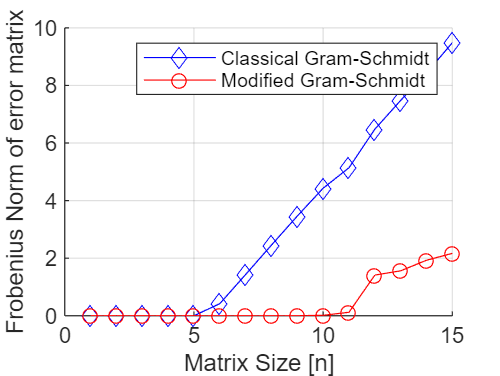

for n=2:16
a= hilb(n); % n is the size of the matrix
[q_gs,r1] = gschmidt(a); %using algorithm classical Gram--Schmidt
[q_mgs,r2] = mgschmidt(a); %using algorithm modified Gram-Schmidt

err_gs(n-1) = norm(q_gs'*q_gs - eye(n),'fro');
err_mgs(n-1) = norm(q_mgs'*q_mgs - eye(n),'fro');

end 


figure;
hold on 
grid on 
plot(err_gs,'b-d')
plot(err_mgs,'r-o')

ylabel('Frobenius Norm of error matrix');
xlabel('Matrix Size [n]')
legend('Classical Gram-Schmidt','Modified Gram-Schmidt');

**For small Hilbert matrices, both Classical and Modified Gram-Schmidt give similar (small) errors because the system is not too ill-conditioned. However, as the matrix size grows, Hilbert matrices become extremely ill-conditioned, causing the Classical Gram-Schmidt method to accumulate larger rounding errors. Modified Gram-Schmidt is more numerically stable, so its error remains lower for larger n. That’s why the plot shows Classical GS errors increasing significantly, while Modified GS errors stay relatively small.**

## **Question 4: (20 marks)**

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


$M\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$,  $M \in \mathbb{R}^{m\times n}$ with $m>n$, $\textbf{a} \in \mathbb{R}^{n}$. $M$ is also called the Vandermonde Matrix.

You are given the following data, your data is loaded and plotted in the cell below. Make sure the provided data files are present in the same directory as this script.

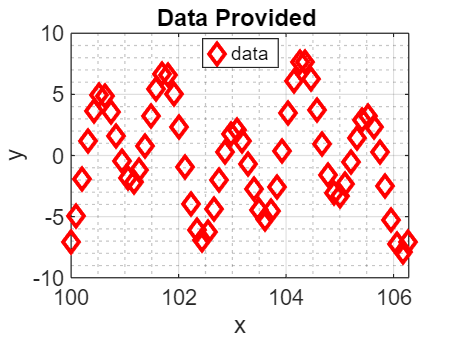

load('Asst3_data_Q4.mat'); % load the data 

x = x_given;
y = y_given; 

figure
plot(x,y, 'rd',"LineWidth",2,"DisplayName",'data')
legend("Location","best") 
xlabel('x') ;ylabel('y')
grid on; grid minor
title('Data Provided ')

a. Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *Vandermonde_Matrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [ 1; 2; 3];
MatrixTest = Vandermonde_Matrix(X,3)

MatrixTest =      1     1     1     1
     1     2     4     8
     1     3     9    27


b. Suppose we choose to model the provided data with a polynomial of **degree 17**. Using the cell below, fit a polynomial of degree 17**, **i.e. $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$. Select an appropriate algorithm mentioned in Question 2 to find the QR decomposition, justify your choice. You should use the Forward and Backward Substitution which you wrote in the previous Assignment. In order to use the funcitons which used in the previous assignment, you can include those in the Appendix.

% write your code here 
%build our vandermonde matrix with degree 17 
M = Vandermonde_Matrix(x,17);

%use modified gram schmidt from last question for numerical stability
[Q,R] = mgschmidt(M);

%solve Ra = Q^T_y using backward sub because R is upper triangular 
Qt_y = Q' * y;
a_coeff = backward_sub(R, Qt_y);




**I used the modified Gram-Schmidt because a 17th degree polynomial means our Vandermonde matrix can be ill-conditioned. (and I was confused by the wording and wasn't sure if the question was trying to say use an algorithm from Q3, therefore no householder.)**

Now that you have obtained the coefficients, $a_i,  \;\;0\leq i \leq17$ , for the polynomial model, $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$. Since the input data was linearly spaced between 100 to $100+2\pi \;$, you can use 200 linearly spaced points to test the performance of your model.

In the cell below, use the data you used to build the model as reference to test the performance of the obtained model by plotting it on the same plot.  Make sure your plots axis are labeled and the plots must contain a title and a legend. 

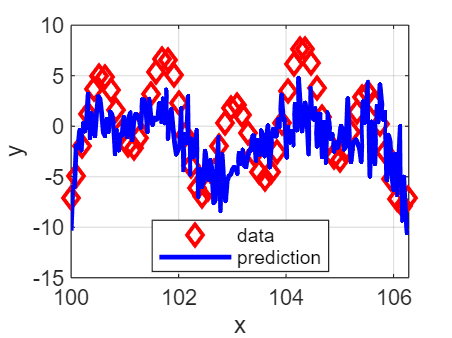

%----------------------------------------------------------------
x_test = linspace(100+0,100+2*pi,200);  % generate test data 
x_test =x_test';
%----------------------------------------------------------------

Mtest = Vandermonde_Matrix(x_test,17); % build vandermonde matrix at the test data

y_prediction_part_a = Mtest*a_coeff;    % The variable y_prediction_part_a  is the prediction of the function p(x) at the test data, 
                                        % The variable a_coeff is the vector containing the coefficients which you found in the previous part
                                        % You may change the variable names to your liking. 

plot(x,y, 'rd',"LineWidth",2,"DisplayName",'data')
hold on 
plot(x_test,y_prediction_part_a, 'b-',"LineWidth",2,"DisplayName",'prediction')

legend("Location","best") 
xlabel('x') ;ylabel('y')
grid on; grid minor
legend 
xlabel('x') ;ylabel('y')
grid on; grid minor

c. Is the model you obtained accurate? Investigate the reason behind the poor performance of the model and suggest a method to improve the model performance. Explain your rationale and justify your choice.

**The model obtained is not accurate, as shown by the significant mismatch between data points and predictions. Usually with a high degree polynomial, there's a risk of overfitting, but our current model doesnt even fit the training data well, so this suggests numerical computation issues rather than overfitting. Potential reasons for poor performance include numerical instability and data scaling issues. To fix this, I will normalize x-values to centre and scale data before constructing the Vandermonde matrix. **

d. If the polynomial model you obtained in part b is not accurate, make appropriate changes to data to fit a polynomial model of order 17 shown in part a. Use the cell below to write your code. Select an appropriate algorithm mentioned in Question 2 to find the QR decomposition, justify your choice. Use the Forward/Backward Substitution you wrote in Assignment 2.

Similar to part b, plot the obtained model along with the data used to build the model. Make sure your plots axis are labeled and the plots must contain a title and a legend. 

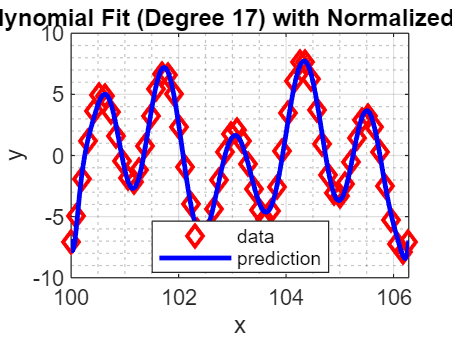


%normalize the x values to improve numerical stability 
x_normalized = (x - mean(x)) / std(x);

%build vandermonde matrix with normalized x values 
M_norm = Vandermonde_Matrix(x_normalized, 17);

[Q, R] = mgschmidt(M_norm);


Qt_y = Q' * y;
a_coeff_norm = backward_sub(R, Qt_y);

%for prediction, we need to normalize test points the same way
x_test_normalized = (x_test - mean(x)) / std(x);
Mtest_norm = Vandermonde_Matrix(x_test_normalized, 17);

%our predictions
y_prediction = Mtest_norm * a_coeff_norm;

%now plot!
figure;
plot(x, y, 'rd', 'LineWidth', 2, 'DisplayName', 'data')
hold on
plot(x_test, y_prediction, 'b-', 'LineWidth', 2, 'DisplayName', 'prediction')
title('Polynomial Fit (Degree 17) with Normalized Data')
xlabel('x')
ylabel('y')
legend('Location', 'best')
grid on
grid minor

Write a brief summary on how you obtained the correct model.

**I improved the polynomial fitting by implementing data normalization to address numerical instability issues. The original model performed poorly because the x-values around 100 led to extreme scaling problems when raised to high powers in the 17th-degree Vandermonde matrix. By normalizing the x-values to have zero mean and unit standard deviation before constructing the Vandermonde matrix, I significantly improved the numerical conditioning of the system.**

## Question 5: (10 marks) 

You are tasked with designing a computer program for obtaining polynomial models using least squares approximation. This would typically require the solution of an overdetermined system $\mathbf{A} \mathbf{x} = \mathbf{b}$, where the matrix $\mathbf{A}$ is a Vandermonde matrix known for being ill-conditioned. You have access to a standard numerical library (such as MATLAB, for example) with the following methods available to you that you can use without modification:

- Fundamental matrix and vector operations (multiplication, addition, etc.)

- $\text{Norm}(\mathbf{A}, n)$: Returns the $L_n$ norm of $\mathbf{A}$.

- $[\mathbf{L}, \mathbf{U}, \mathbf{P}] = \text{PLU}(\mathbf{A})$: Returns $\mathbf{L}$, $\mathbf{U}$, and $\mathbf{P}$ such that $\mathbf{P} \mathbf{A} = \mathbf{L} \mathbf{U}$ (Partial pivoting).

- $[\mathbf{L}, \mathbf{U}] = \text{LU}(\mathbf{A})$: Returns $\mathbf{L}$ and $\mathbf{U}$ such that $\mathbf{L} \mathbf{U} = \mathbf{A}$(No pivoting).

- $\mathbf{A}^T = \text{transp}(\mathbf{A})$: Returns the transpose of $\mathbf{A}$.

- $\mathbf{L} = \text{Chol}(\mathbf{A})$: Returns $\mathbf{L}$ such that $\mathbf{A} = \mathbf{L} \mathbf{L}^T$ (Uses Cholesky decomposition – $\mathbf{A}$ must be symmetric positive definite).

- $[\mathbf{Q}, \mathbf{R}] = \text{MGSqr}(\mathbf{A})$: Returns $\mathbf{Q}$ and $\mathbf{R}$ such that $\mathbf{A} = \mathbf{Q} \mathbf{R}$ (Uses the modified Gram-Schmidt algorithm).

- $[\mathbf{Q}, \mathbf{R}] = \text{HouseholderQR}(\mathbf{A})$: Returns $\mathbf{Q}$ and $\mathbf{R}$ such that $\mathbf{A} = \mathbf{Q} \mathbf{R}$ (Uses Householder reflections).

- $[\mathbf{Q}, \mathbf{R}] = \text{GivensQR}(\mathbf{A})$: Returns $\mathbf{Q}$ and $\mathbf{R}$ such that $\mathbf{A} = \mathbf{Q} \mathbf{R}$ (Uses Givens rotations).

- $\mathbf{y} = \text{FwdSub}(\mathbf{L}, \mathbf{b})$: Returns $\mathbf{y}$ such that $\mathbf{L} \mathbf{y} = \mathbf{b}$ (**L** must be lower triangular).

- $\mathbf{x} = \text{BwdSub}(\mathbf{U}, \mathbf{y})$: Returns $\mathbf{x}$ such that $\mathbf{U} \mathbf{x} = \mathbf{y}$ ( $\mathbf{U}$ must be upper triangular).

You are tasked with solving this problem using **Tikhonov Regularization**. Write a MATLAB program that computes $\mathbf{x}$, given $\mathbf{A}$and $\mathbf{b}$. You can use any of the functions outlined above if needed.  

function x = tikhonov_regularization(A, b, lambda)
    %lambda is the regularization parameter
    
    %we're just solving the closed-form solution: x = (A^T A + λI)^(-1) A^T b
    [m, n] = size(A);

    ATA = transp(A) * A;
    regularized_matrix = ATA + lambda * eye(n);
    ATb = transp(A) * b;
    
    %use householder for stability
    [Q, R] = HouseholderQR(regularized_matrix);
    y = transp(Q) * ATb;
    x = BwdSub(R, y);
    
end

There are a number of possible implementations or answers to this problem. Provide the pseudocode and explain the rationale behind the approach you have used.

**pseudocode: **

**m, n = size(A)**

**ATA = transpose(A) * A**

**RegularizedMatrix = ATA + lambda * IdentityMatrix(n)**

**ATb = transpose(A) * b**

**Q, R = HouseholderQR(RegularizedMatrix)**

**y = transpose(Q) * ATb**

**x = BackwardSubstitution(R, y)**

**Rationale:**

**I chose Householder QR decomposition because it's numerically more stable than other methods like LU for solving the regularized system. Using Tikhonov Regularization, we are able to deal with the problem of Vandermonde matrices becoming increasingly ill-conditioned as we get to higher degree polynomials. I implemented the solution without explicitly computing the inverse of (A^T A + λI), which avoids additional numerical instability that would arise from matrix inversion. Instead, the QR decomposition approach provides a more direct and stable way to solve the regularized system. Therefore, Tikhonov Regularization serves as a better approach than our previous one for solving for the solution vector x.**

## **Appendix**

**Write your funcitons here.**

### **Question 3 Code**

function [Q,R] = gschmidt(A)
    %basically just implementing the pseudocode from slide 17 of Lecture 9
    %QR decomp

    [n,m] = size(A);

    %initialize our output QR matricies 
    Q = zeros(n,m);
    R = zeros(m,m);

    %r11 = ||a1||
    R(1,1) = norm(A(:,1));
    %q1 = a1/r11
    Q(:,1) = A(:,1)/R(1,1);

    %for j = 2,3,...m
    for j = 2:m
        p = 0;
        for i = 1:(j-1)
            R(i,j) = Q(:,i)' * A(:,j);
            p = p + R(i,j) * Q(:,i);
        end
        v = A(:,j) - p;
        R(j,j) = norm(v);
        Q(:,j) = v / R(j,j);
    end
end

function [Q,R] = mgschmidt(A)
    %implementing the pseudocode from slide 19 of lecture 9 QR decomp

    [n,m] = size(A);
    Q = zeros(n,m);
    R = zeros(m,m);

    for i=1:m
        R(i,i) = norm(A(:,i));
        Q(:,i) = A(:,i) / R(i,i);
        for j = (i+1):m
            R(i,j) = Q(:,i)' * A(:,j);
            A(:,j) = A(:,j) - R(i,j) * Q(:,i);
        end
    end
end

### **Question 4 Code**

function M = Vandermonde_Matrix(x, degree)

N = length(x);
M = zeros(N, degree+1);

%construct the Vandermonde Matrix
for i = 1:N
    for j = 0:degree
        M(i, j+1) = x(i)^j;
    end
end

end

function x = forward_sub(L, b)
%pretty much taking slide 24 in lecture 3 and converting it into code

n = length(b);
%solution vector
x = zeros(n,1);

for i = 1:n
    %subtract the known contributions from previous entries:
    %L(i,1:i-1) * x(1:i-1) computes the dot product for row i
    x(i) = (b(i) - L(i,1:i-1)*x(1:i-1)) / L(i,i);
end

end


function x = backward_sub(U, b)
%pretty much taking slide 25 in lecture 3 and converting it into code

n = length(b);
x = zeros(n,1);

%we go from the bottom row (i = n) up to the top row (i = 1)
for i = n:-1:1
    %subtract the contributions from already-solved x(j) with j>i
    % L(i,i+1:n)*x(i+1:n) is the dot product for row i from columns i+1 to n
    x(i) = (b(i) - U(i,i+1:n)*x(i+1:n)) / U(i,i);
end

end